## Identifying a model for the gantry crane

## Generate input data

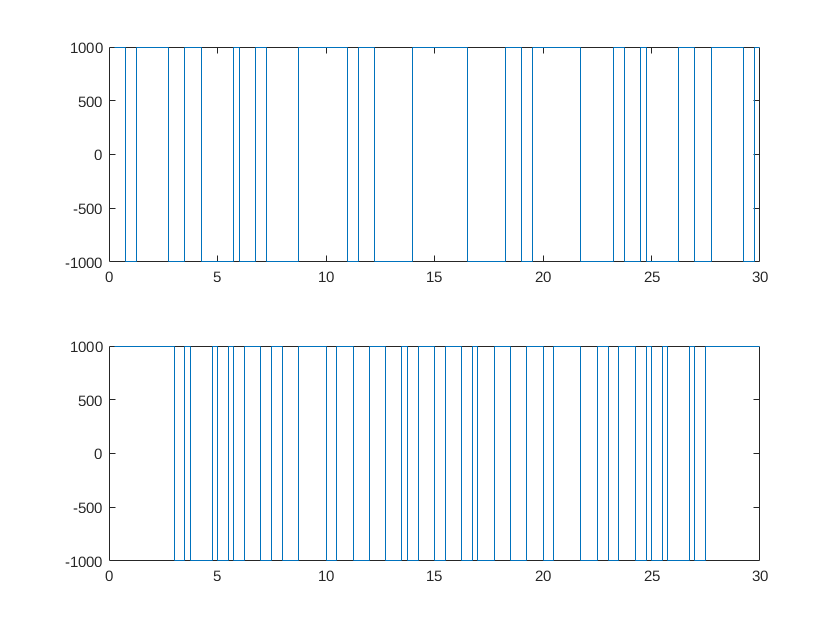


h = 0.25;
N = 120;
Tfinal = N*h;   
uu = idinput(N, 'rbs', [0, 0.5]);
forceMagnitude = 1e3;
u1 = forceMagnitude*uu(1:N/2);
u1v = forceMagnitude*uu(N/2+1:N);
t = (1:N)'*h;
input1 = cat(2, t, cat(1, u1, flipud(u1)));
input1v = cat(2, t, cat(1, u1v, flipud(u1v)));

figure(1)
subplot(211)
stairs(input1(:,1), input1(:,2))
subplot(212)
stairs(input1v(:,1), input1v(:,2))

## Load data

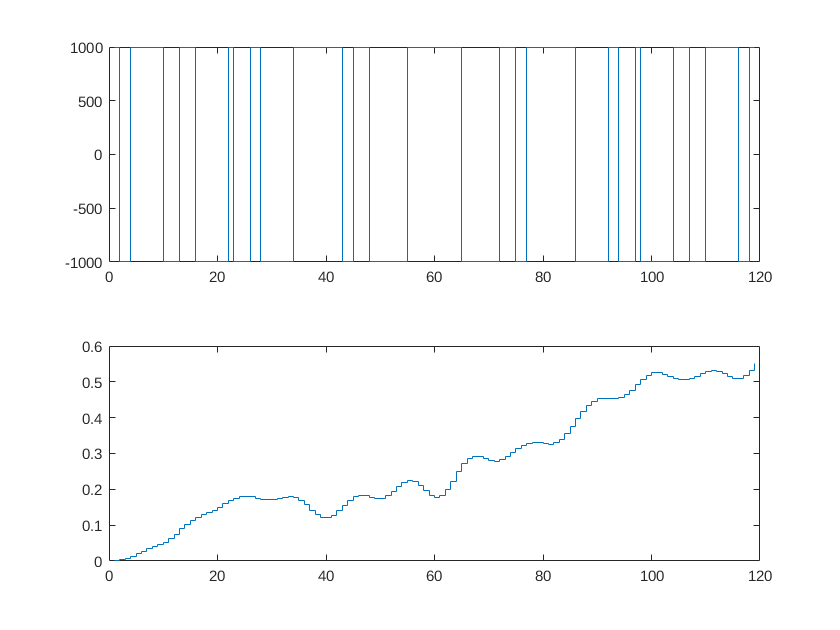

uident = out.simout.Data(3:end,1);
yident = out.simout.Data(3:end,2);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

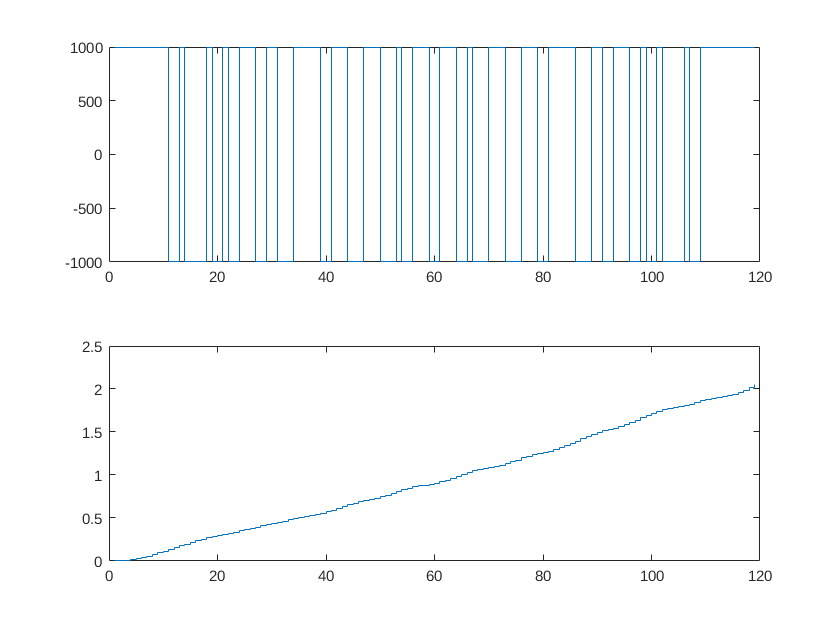



uval = out.simout2.Data(3:end,1);
yval = out.simout2.Data(3:end,2);
figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.918 z^-1 + 0.917 z^-2               
                                                   
  B(z) = -1.892e-08 z^-1 + 9.837e-07 z^-2          
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 97.55% (prediction focus)
FPE: 1.719e-05, MSE: 1.554e-05                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.907 z^-1 + 0.9055 z^-2              
                                                   
  B(z) = 2.601e-07 z^-2 + 1.325e-06 z^-3           
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 97.65% (prediction focus)
FPE: 1.584e-05, MSE: 1.432e-05                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                       
  A(z) = 1 - 3.619 z^-1 + 5.206 z^-2 - 3.551 z^-3 + 0.964 z^-4            
                                                                          
  B(z) = 2.029e-08 z^-1 + 2.516e-07 z^-2 + 1.956e-07 z^-3 + 1.562e-08 z^-4
                                                                          
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.82% (prediction focus)
FPE: 1.083e-07, MSE: 8.845e-08                   



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                       
  A(z) = 1 - 3.168 z^-1 + 3.983 z^-2 - 2.717 z^-3 + 1.583 z^-4 - 1.111 z^-5 + 0.4293 z^-6                 
                                                                                                          
  B(z) = 4.744e-09 z^-1 + 2.509e-07 z^-2 + 3.648e-07 z^-3 + 1.8e-07 z^-4 + 7.949e-08 z^-5 + 3.972e-08 z^-6
                                                                                                          
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.85% (prediction focus)
FPE: 7.442e-08, MSE: 5.486e-08                   



% sixth order model, five zeros, six poles, two delays
arx662 = arx(iddta1, [6, 6, 2])

arx662 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 3.169 z^-1 + 3.986 z^-2 - 2.716 z^-3 + 1.577 z^-4 - 1.105 z^-5 + 0.4274 z^-6                   
                                                                                                            
  B(z) = 2.535e-07 z^-2 + 3.658e-07 z^-3 + 1.765e-07 z^-4 + 7.878e-08 z^-5 + 4.514e-08 z^-6 - 1.069e-08 z^-7
                                                                                                            
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.85% (prediction focus)
FPE: 7.435e-08, MSE: 5.481e-08                   



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                            
  A(z) = 1 - 3.025 z^-1 + 3.689 z^-2 - 2.434 z^-3 + 1.158 z^-4 - 0.5939 z^-5 + 0.3339 z^-6 - 0.3061 z^-7 + 0.1784 z^-8                         
                                                                                                                                               
  B(z) = -3.824e-09 z^-1 + 2.719e-07 z^-2 + 3.911e-07 z^-3 + 2.572e-07 z^-4 + 2.395e-07 z^-5 + 1.557e-07 z^-6 + 7.053e-09 z^-7 + 3.824e-08 z^-8
                                                                                                                                               
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using 


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 2])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                            
                                                                                                                                                               
  A(z) = 1 - 3 z^-1 + 3.609 z^-2 - 2.358 z^-3 + 1.103 z^-4 - 0.5365 z^-5 + 0.1765 z^-6 + 0.1055 z^-7 - 0.2648 z^-8 + 0.1951 z^-9 - 0.1452 z^-10 + 0.2456 z^-11 
                                                                                                                                            - 0.1303 z^-12     
                                                                                                                                                               
                                                                                                                                                               
  B(z) = 2.648e-07 z^-2 + 3.9


% Fourth order state space model
ss4 = n4sid(iddta1, 4);

% Sixth order state space model
ss6 = n4sid(iddta1, 6);


## Compare models

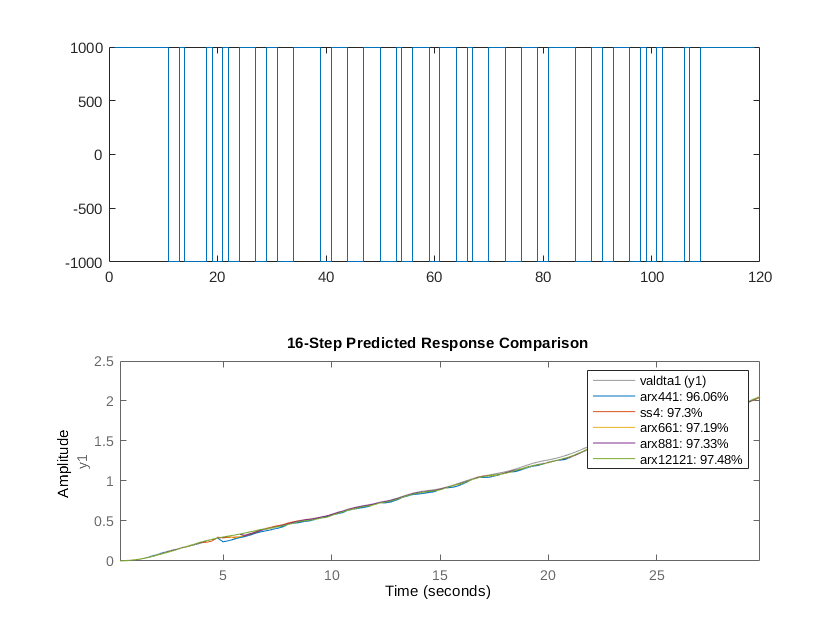

compare(valdta1, arx441, ss4, arx661, arx881, arx12121, 16)

aic(arx441, ss4, arx661, ss6, arx881, arx12121)

Model quality according to the "nAIC" measure:
  -16.0392  -16.4362  -16.4159  -16.3688  -16.4234  -16.3668



## Export models for use in Simulink

[num, den] = tfdata(tf(arx441))

num = 1×1 cell array
    {[0 2.0286e-08 2.5161e-07 1.9561e-07 1.5624e-08]}


den = 1×1 cell array
    {[1 -3.6194 5.2062 -3.5508 0.9640]}


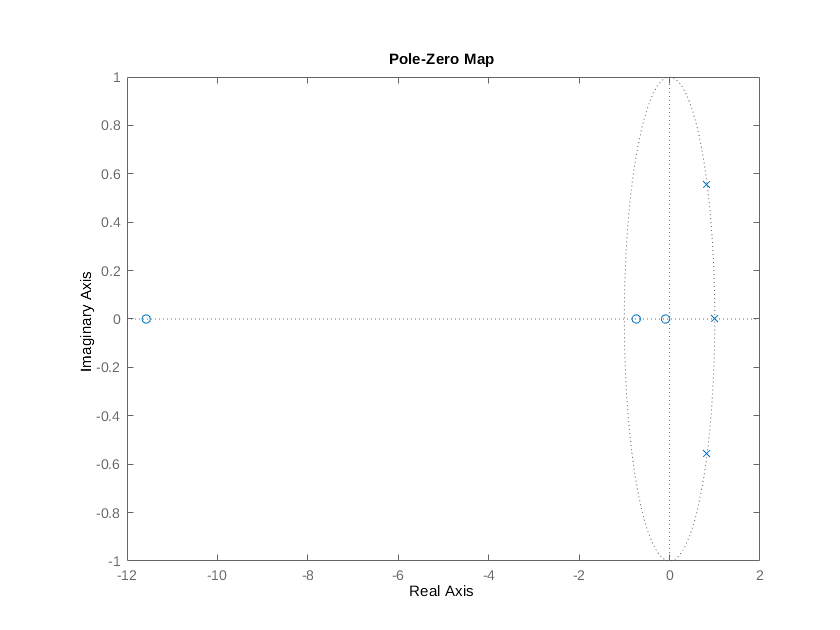

figure()
clf
pzmap(arx441)

save crane_sysid_result.mat arx441 arx661 ss4 ss6
